% Supplementary Analysis 2 - Domain-specificity of adult-to-pediatric model translation

clc;
clear all;

% Add statistical scripts to path
addpath('/Shared/boeslab/Users/jcgriffis/statistical_scripts/Misc_Code');
addpath('/Shared/boeslab/Users/jcgriffis/vips_psom_prediction/final_archive_scripts');

% Analysis parameters
min_stroke_age = 0; % Minimum stroke onset age (years)
min_test_age = 0; % Minimum age at PSOM (years)
min_test_interval = 0.5; % Minimum interval between onset and assessment (years)
min_freq = 1; % Minimum lesion frequency
pos_only = 1; % Use only positive model weights for predictions
get_vips_preds = 1; % load test fold predictions for pediatric models when generating adult model predictions

% Path to adult SM model
sm_col = "gpb_dif";
sm_outcome = "contra_motor";    
sm_dir = '/Shared/boeslab/Users/jcgriffis/vips_psom_prediction/registry_models/motor';    
sm_model_dir = 'plsr_all_lesion_d0_all_flip_ui';
sm_model_path = fullfile(sm_dir, sm_col, sm_model_dir); 

% Path to adult Lang model
lang_col = "mae_token";
lang_outcome = "worst_lang";    
lang_dir = '/Shared/boeslab/Users/jcgriffis/vips_psom_prediction/registry_models/language';   
lang_model_dir = 'plsr_all_lesion_d0_all_ui';    
lang_model_path = fullfile(lang_dir, lang_col, lang_model_dir); 

% Get predicted pediatric scores (SM)
[cfg_sm, beh_csv] = load_and_format_vips_lesions(sm_outcome);

All subjects with behavioral data have lesion files, N=528 patients will be included


[ui_pred_sm2, ui_pred_sm, vips_pred_sm] = apply_ui_model_vips(sm_col, sm_model_path, cfg_sm, beh_csv, get_vips_preds,...
    sm_outcome, min_stroke_age, min_test_age, min_test_interval, min_freq, 0, pos_only);

    "Applying model for "    "gpb_dif"



% Get predicted pediatric scores (lang)
[cfg_lang, beh_csv] =  load_and_format_vips_lesions(lang_outcome);

All subjects with behavioral data have lesion files, N=528 patients will be included


[ui_pred_lang2, ui_pred_lang, vips_pred_lang] = apply_ui_model_vips(lang_col, lang_model_path, cfg_lang, beh_csv, get_vips_preds,...
    lang_outcome, min_stroke_age, min_test_age, min_test_interval, min_freq, 0, pos_only);

    "Applying model for "    "mae_token"



% Get indices of patients that meet inclusion criteria
inc_ind = find(all([beh_csv.stroke_age >= min_stroke_age, beh_csv.test_age >= min_test_age, beh_csv.yrs2test >= min_test_interval],2));

% Subset dataset and predictions to retain only included patients
beh_csv = beh_csv(inc_ind,:);
ui_pred_sm = ui_pred_sm(inc_ind);
ui_pred_sm2 = ui_pred_sm2(inc_ind);
ui_pred_lang = ui_pred_lang(inc_ind);
ui_pred_lang2 = ui_pred_lang2(inc_ind);
disp(['N=' num2str(length(inc_ind)) ' included pediatric patients'])

N=469 included pediatric patients



% Define standardized covariates
covs = zscore([beh_csv.lh_vol, beh_csv.rh_vol, beh_csv.stroke_age, beh_csv.yrs2test]);

% Fit ordinal logistic regression models to estimate aOR and compare against base models

% Reverse code and re-code categories to set reference category to unimpaired (SM outcome)
Y1 = zeros(length(inc_ind),1);
Y1(beh_csv.(sm_outcome)==0)=3;
Y1(beh_csv.(sm_outcome)==0.5)=2;
Y1(beh_csv.(sm_outcome)==1)=1;
Y1(beh_csv.(sm_outcome)==2)=0;
Y1 = categorical(Y1);

% Reverse code and re-code categories to set reference category to unimpaired (LANG outcome)
Y2 = zeros(length(inc_ind),1);
Y2(beh_csv.(lang_outcome)==0)=3;
Y2(beh_csv.(lang_outcome)==0.5)=2;
Y2(beh_csv.(lang_outcome)==1)=1;
Y2(beh_csv.(lang_outcome)==2)=0;
Y2 = categorical(Y2); 

% Fit base OLR models
mdl1a = fitmnr(covs, Y1, 'ModelType', 'ordinal', 'PredictorNames', {'LH Volume', 'RH Volume', 'Age at Stroke', 'Time to Test'}); % SM Model
mdl2a = fitmnr(covs, Y2, 'ModelType', 'ordinal', 'PredictorNames', {'LH Volume', 'RH Volume', 'Age at Stroke', 'Time to Test'}); % LANG Model   

% Add adult predictions (SM)
mdl1b = fitmnr([covs, zscore(ui_pred_sm)], Y1, 'ModelType', 'ordinal', 'IterationLimit', 1000, 'PredictorNames', {'LH Volume', 'RH Volume', 'Age at Stroke', 'Time to Test', 'Adult Model'})

mdl1b = Multinomial regression with ordinal responses

                      Value         SE        tStat        pValue  
                     ________    ________    ________    __________

    (Intercept_0)     -2.6745     0.18312     -14.605             0
    (Intercept_1)    -0.99663     0.11213     -8.8885    6.1959e-19
    (Intercept_2)     0.20597    0.099633      2.0673      0.038709
    LH Volume        -0.13599     0.14397    -0.94456       0.34488
    RH Volume        -0.37233     0.15508     -2.4009      0.016354
    Age at Stroke    -0.21268    0.092468     -2.3001      0.021445
    Time to Test      0.09282    0.089257      1.0399       0.29838
    Adult Model        1.2676     0.19289      6.5715    4.9

% Add adult predictions (Lang)
mdl2b = fitmnr([covs, zscore(ui_pred_lang)], Y2, 'ModelType', 'ordinal', 'IterationLimit', 1000, 'PredictorNames', {'LH Volume', 'RH Volume', 'Age at Stroke', 'Time to Test', 'Adult Model'})

mdl2b = Multinomial regression with ordinal responses

                      Value         SE        tStat       pValue  
                     ________    ________    _______    __________

    (Intercept_0)     -3.0685      0.2135    -14.372             0
    (Intercept_1)     -1.9494     0.14597    -13.355     1.109e-40
    (Intercept_2)     -1.0962     0.11511    -9.5226    1.6888e-21
    LH Volume        -0.40632     0.29366    -1.3836       0.16648
    RH Volume         0.29839    0.090844     3.2846     0.0010213
    Age at Stroke    -0.29931     0.11484    -2.6063     0.0091532
    Time to Test      0.15418     0.10471     1.4725       0.14089
    Adult Model        1.0909     0.29467     3.7022    0.00021373




% Get coeffs and CIs
mdl1b_ci = coefCI(mdl1b); mdl1b_ci = exp(mdl1b_ci(4:end,:));
mdl2b_ci = coefCI(mdl2b); mdl2b_ci = exp(mdl2b_ci(4:end,:));
mdl1b_coef = exp(mdl1b.Coefficients.Value(4:end));
mdl2b_coef = exp(mdl2b.Coefficients.Value(4:end));

% Likelihood ratio tests of expanded vs. base models
p_llr_sm = 1-chi2cdf(-2*(mdl1a.LogLikelihood-mdl1b.LogLikelihood),1) % SM 

p_llr_sm = single
0

p_llr_lang = 1-chi2cdf(-2*(mdl2a.LogLikelihood-mdl2b.LogLikelihood),1) % Lang

p_llr_lang = single
1.6963e-04

% Add LANG predictions to expanded SM model and do likelihood ratio test
mdl1ab = fitmnr(zscore([covs, ui_pred_sm, ui_pred_lang]), Y1, 'ModelType', 'ordinal', 'IterationLimit', 1000, 'PredictorNames', {'LH Volume', 'RH Volume', 'Age at Stroke', 'Time to Test', 'Same Domain', 'Other Domain'})

mdl1ab = Multinomial regression with ordinal responses

                      Value         SE        tStat        pValue  
                     ________    ________    ________    __________

    (Intercept_0)     -2.6759     0.18317     -14.609             0
    (Intercept_1)    -0.99622     0.11211     -8.8858    6.3467e-19
    (Intercept_2)      0.2068    0.099658      2.0751       0.03798
    LH Volume        -0.03591     0.27635    -0.12994       0.89661
    RH Volume        -0.39074     0.16001     -2.4419      0.014611
    Age at Stroke    -0.20853    0.092925     -2.2441      0.024826
    Time to Test     0.095609    0.089341      1.0702       0.28455
    Same Domain        1.3006     0.20665      6.2936    3.

p_llr_1ab = 1-chi2cdf(-2*(mdl1b.LogLikelihood-mdl1ab.LogLikelihood),1) % SM 

p_llr_1ab = single
0.6583

% Add SM predictions to expanded LANG model and do likeilihood ratio test
mdl2ab = fitmnr(zscore([covs, ui_pred_lang, ui_pred_sm]), Y2, 'ModelType', 'ordinal', 'IterationLimit', 1000, 'PredictorNames', {'LH Volume', 'RH Volume', 'Age at Stroke', 'Time to Test', 'Same Domain', 'Other Domain'})

mdl2ab = Multinomial regression with ordinal responses

                      Value        SE        tStat       pValue  
                     ________    _______    _______    __________

    (Intercept_0)     -3.0853    0.21437    -14.393             0
    (Intercept_1)     -1.9586    0.14666    -13.355    1.1078e-40
    (Intercept_2)      -1.104    0.11591    -9.5251    1.6483e-21
    LH Volume         -0.4359    0.29544    -1.4754        0.1401
    RH Volume        0.087757    0.17139    0.51203       0.60863
    Age at Stroke    -0.30902    0.11532    -2.6798     0.0073663
    Time to Test      0.16084     0.1049     1.5333       0.12521
    Same Domain       0.91596    0.31321     2.9244     0.0034514
    

p_llr_2ab = 1-chi2cdf(-2*(mdl2b.LogLikelihood-mdl2ab.LogLikelihood),1) % lang

p_llr_2ab = single
0.1363

% Get coeffs and CIs
mdl1ab_ci = coefCI(mdl1ab); mdl1ab_ci = exp(mdl1ab_ci(4:end,:));
mdl2ab_ci = coefCI(mdl2ab); mdl2ab_ci = exp(mdl2ab_ci(4:end,:));
mdl1ab_coef = exp(mdl1ab.Coefficients.Value(4:end));
mdl2ab_coef = exp(mdl2ab.Coefficients.Value(4:end));

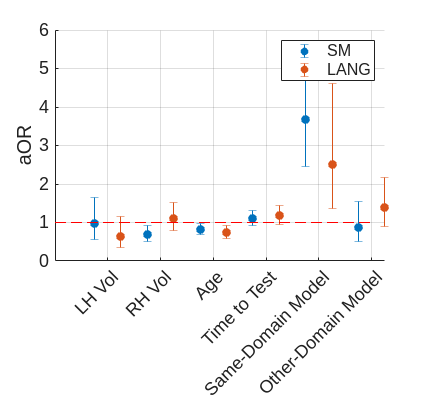

% Plot aORs and 95% CIs for expanded models with other-domain predictions
clf;
errorbar([0.75,1.75,2.75,3.75,4.75, 5.75], mdl1ab_coef, mdl1ab_coef-mdl1ab_ci(:,1), mdl1ab_ci(:,2)-mdl1ab_coef, 'LineStyle', 'none', 'Marker', '.', 'MarkerSize', 20,'Color', [0, 0.447, 0.741]);
hold on;
errorbar([1.25,2.25,3.25,4.25, 5.25, 6.25], mdl2ab_coef, mdl2ab_coef-mdl2ab_ci(:,1), mdl2ab_ci(:,2)-mdl2ab_coef, 'LineStyle', 'none', 'Marker', '.', 'MarkerSize', 20,'Color', [0.85, 0.325, 0.098]);
line([0, 6], [1, 1], 'LineStyle', '--', 'Color', 'r', 'LineWidth', 0.5);
ylabel('aOR'); grid on; legend({'SM', 'LANG'});
set(gca, 'Xtick', 1:1:6);
set(gca, 'XtickLabel', {'LH Vol', 'RH Vol', 'Age', 'Time to Test', 'Same-Domain Model' 'Other-Domain Model'});
set(gca, 'XtickLabelRotation', 45);
set(gca, 'FontSize', 14);
set(gcf, 'color', 'w');
set(gcf, 'position', [0, 0, 425, 400]); box off;